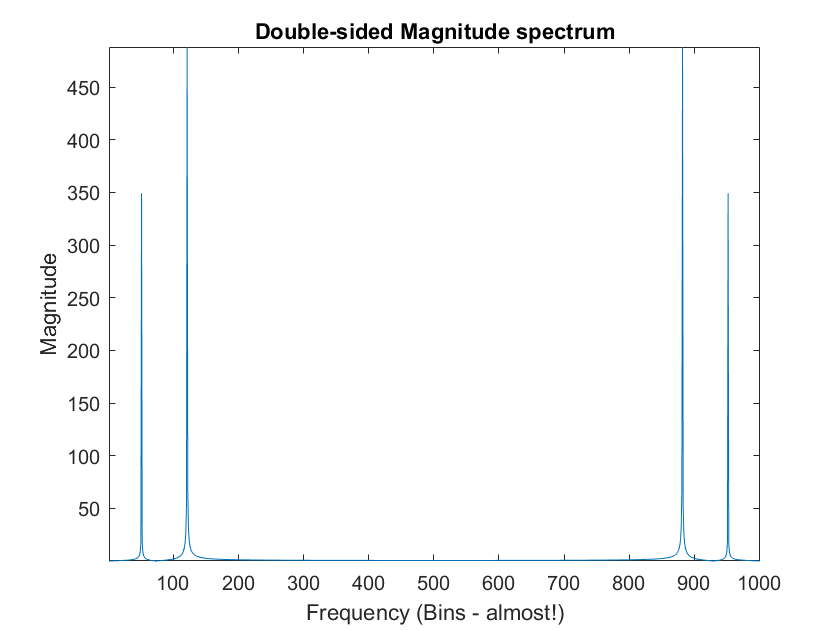

t = 0:0.001:1;
signal =0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
N = length(signal);
fs = 62.5; % 62.5 samples per second
fnyquist = fs/2; %Nyquist frequency

plot(abs(fft(signal)))
xlabel('Frequency (Bins - almost!)')
ylabel('Magnitude');
title('Double-sided Magnitude spectrum');
axis tight

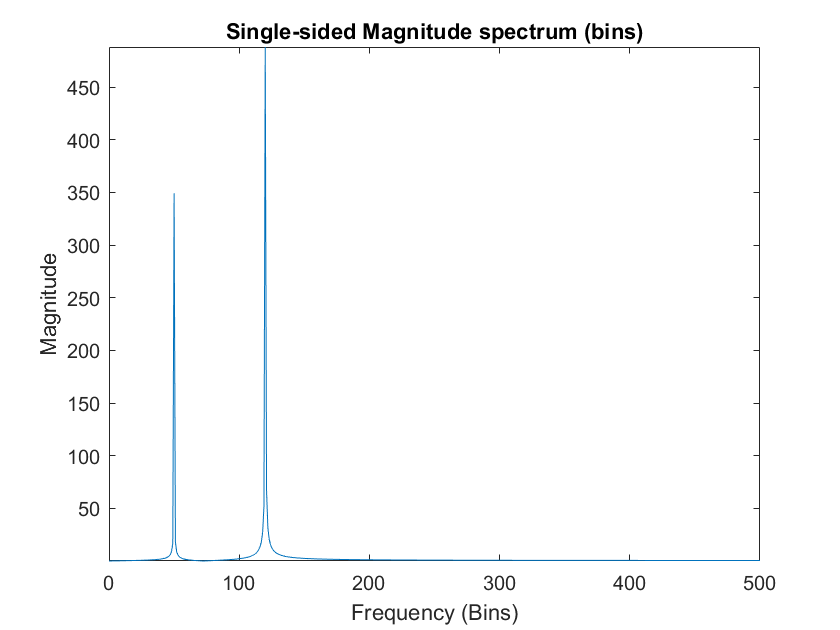


%single sided
X_mags = abs(fft(signal));
fax_bins = [0 : N-1]; %frequency axis in bins
N_2 = ceil(N/2);
plot(fax_bins(1:N_2), X_mags(1:N_2))
xlabel('Frequency (Bins)')
ylabel('Magnitude');
title('Single-sided Magnitude spectrum (bins)');
axis tight